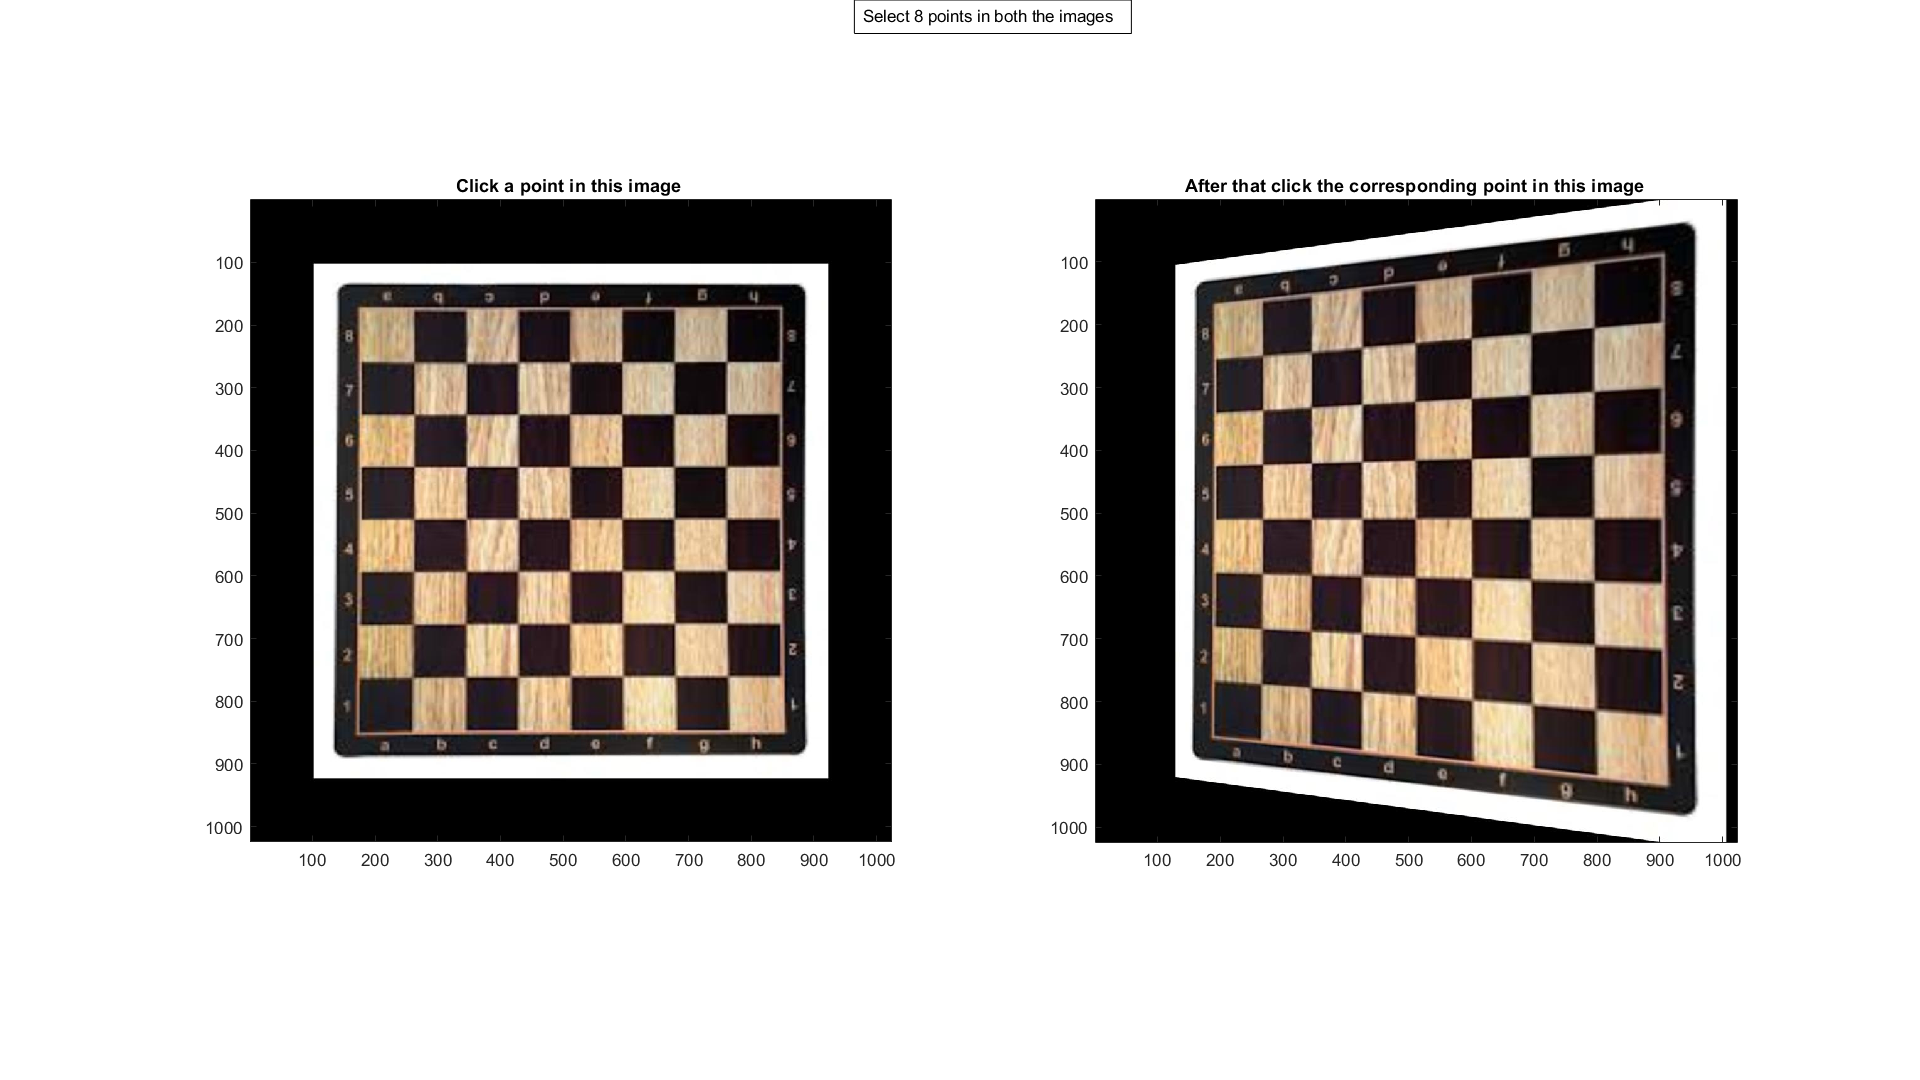

clc
% clear 
% close all
%% Rerun of code

% This section is only useful if you have done some mistake while selection
% of points and you want to reselct the points, or if you want to see what 
% happens to the image with diffent standard transformations.

% When You rerun the code it will first ask you if you want to rerun with
% the same images selected you can input 1 or 0 according to your choice

% Then it will ask you if you want to reselct the points. 
clear re
clearvars -except a a1 b x y x1 y1
ex = exist('a','var');
reim = 1;
repoint = 1;
if ex == 1
    re = input('Do you want to rerun using the same image ? Press 1 for yes and 0 for no : ');
end

ex = exist('re','var');
if ex == 1
    if re==1
        reim = 0;
        repoint = input('Do you want to reselect the points. Press 1 for yes and 0 for no : ');
    else 
        reim = 1;
    end
end

%% Read Input and change to grayscale if color
if reim == 1

[file,path] = uigetfile('*.*');
f1 = fullfile(path,file);
if prod(double(file) == 0) && prod(double(path) == 0)
    return
end
a = imread(f1);                                         % Image to be transformed

[file,path] = uigetfile('*.*');
f1 = fullfile(path,file);
if prod(double(file) == 0) && prod(double(path) == 0)
    return
end
a1 = imread(f1);                                        % Reference image

b = size(a);

a1(isnan(a1)) = 0;
a(isnan(a)) = 0;
end
%% Select points 
% Click a point in the left image then click the corresponding point in the
% right image. n denotes the no. of points to select.

n = 8 ;
Fig = figure('Position', get(0, 'Screensize'));
annotation('textbox',[.445 .5 .4 .5],'String',['Select ',num2str(n),' points in both the images'],'FitBoxToText','on')
subplot(1,2,1)
image(uint8(a));
axis image
colormap gray
title('Click a point in this image ')
a=double(a);
subplot(1,2,2)
image(a1);
axis image
colormap gray
title('After that click the corresponding point in this image ')

%%
if repoint == 1
x = zeros(1,n);
y = zeros(1,n);
x1 = zeros(1,n);
y1 = zeros(1,n);

for i= 1:n
[x0,y0] = ginput(1);                                    % Get input from manual selection of points
hold on
scatter(x0,y0,'filled')                                 % Show the selected point in the image
x(i) = x0;
y(i) = y0;
[x10,y10] = ginput(1);
hold on
scatter(x10,y10,'filled')
x1(i) = x10;
y1(i) = y10;
end

x = x-b(2)/2;
y = y-b(1)/2;
end

close(Fig)
%%
i=0;
B = zeros(1,2*n);
for i1 = 1:2:2*n
    i=i+1;
    B(i1) = x1(i);
    B(i1+1) = y1(i); 
    
end
i=0;
A1 = zeros(2*n,1);
A2 = zeros(2*n,1);
A3 = zeros(2*n,1);
A4 = zeros(2*n,1);
A5 = zeros(2*n,1);
A6 = zeros(2*n,1);
A7 = zeros(2*n,1);
A8 = zeros(2*n,1);
for i1 = 1:2:2*n
    i=i+1;
    A1(i1) = x(i);
    A2(i1) = y(i);
    A3(i1) = 1;
    A7(i1) = -x1(i)*x(i);
    A8(i1) = -y(i)*x1(i);
    A4(i1+1) = x(i);
    A5(i1+1) = y(i);
    A6(i1+1) = 1;
    A7(i1+1) = -x(i)*y1(i);
    A8(i1+1) = -y(i)*y1(i);
end

disp('Choose Transformation')

Choose Transformation


disp('Press')

Press


disp('1 for  Homography Transform')

1 for  Homography Transform


disp('2 for  Affine Transform')

2 for  Affine Transform


disp('3 for  Pure Translation Transform')

3 for  Pure Translation Transform


disp('Any other no. for  Similarity\Rigid Transform')

Any other no. for  Similarity\Rigid Transform



std_transform = input('Enter : ');

switch std_transform

    case 1
%% Homography
        disp('Homography Transform')
        Aa = [A1 A2 A3 A4 A5 A6 A7 A8];
        h = (Aa'*Aa)\Aa'*B';
        A = [h(1) h(2) h(3); h(4) h(5) h(6); h(7) h(8) 1];
        

    case 2
        disp('Affine Transform')
        %% Affine
        Aff = [A1 A2 A3 A4 A5 A6];
        aff = (Aff'*Aff)\Aff'*B';
        A = [aff(1) aff(2) aff(3); aff(4) aff(5) aff(6);0 0 1];
        
    case 3
        disp('Pure Translation Transform')
        Aff = [A1 A2 A3 A4 A5 A6];
        aff = (Aff'*Aff)\Aff'*B';
        A = [1 0 aff(3); 0 1 aff(6);0 0 1];
        
    otherwise
        disp('Similarity Transform')
        Aff = [A1 A2 A3 A4 A5 A6];
        aff = (Aff'*Aff)\Aff'*B';
        A = [aff(1) 0 aff(3); 0 aff(5) aff(6);0 0 1];
        
end

Homography Transform


%%
% A = af;
color = 0;

% Is it color or grayscale
b = size(a);
if size(b,2)==3
color = 1;
end

%Convert to double
a= double(a);                       

%% Transform 

% Bring the origin to the center by this Matrix
trans = [1,0,-b(2)/2;0,1,-b(1)/2;0,0,1];

disp('The transform matrix is ')

The transform matrix is 


disp(A*trans);

    0.9043    0.0034   47.6406
   -0.1899    1.1366   35.3250
   -0.0003    0.0000    1.1612



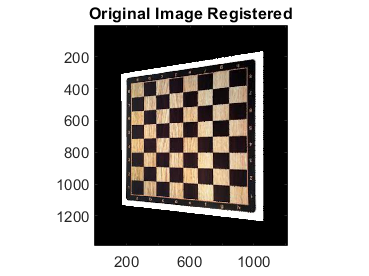

%Transform Happens Here

outx = zeros(b(1),b(2));
outy = zeros(b(1),b(2));

for i = 1:b(1)
    for j = 1:b(2)
        new  = A*trans*[j;i;1];%
        outx(i,j) = round(new(1)/new(3));
        outy(i,j) = round(new(2)/new(3));
    end
end
%% Forming the transformed image
minoutx = min(outx,[],'all');
minouty = min(outy,[],'all');

maxoutx = max(outx,[],'all');
maxouty = max(outy,[],'all');

f = -1*ones(maxouty+abs(minouty)+1,maxoutx+abs(minoutx)+1);

for i = 1:b(1)
    for j = 1:b(2)
        f(outy(i,j)+abs(minouty)+1,outx(i,j)+abs(minoutx)+1,1) = a(i,j,1);
        if color == 1
            f(outy(i,j)+abs(minouty)+1,outx(i,j)+abs(minoutx)+1,2) = a(i,j,2);
            f(outy(i,j)+abs(minouty)+1,outx(i,j)+abs(minoutx)+1,3) = a(i,j,3);
        end
        
    end
end

%% Fill the gaps
%Fill in the gaps By using Median Filter
b1 = size(f);
for i = 2:b1(1)-2
    for j = 2:b1(2)-2
        if f(i,j)==-1
       f(i,j) = median([f(i-1,j-1),f(i-1,j),f(i-1,j+1),f(i,j-1),f(i,j),f(i,j+1),f(i+1,j-1),f(i+1,j),f(i+1,j+1)]);
       if color == 1
       f(i,j,2) = median([f(i-1,j-1,2),f(i-1,j,2),f(i-1,j+1,2),f(i,j-1,2),f(i,j,2),f(i,j+1,2),f(i+1,j-1,2),f(i+1,j,2),f(i+1,j+1,2)]);
       f(i,j,3) = median([f(i-1,j-1,3),f(i-1,j,3),f(i-1,j+1,3),f(i,j-1,3),f(i,j,3),f(i,j+1,3),f(i+1,j-1,3),f(i+1,j,3),f(i+1,j+1,3)]);
       end
        end
    end
end


%% Display the Images
figure;
% subplot(1,2,1)
imagesc(uint8(f));
title('Original Image Registered')
colormap(gray)
axis image

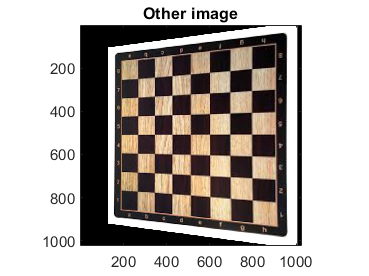

% subplot(1,2,2)
figure;
imagesc(uint8(a1));
colormap(gray)
axis image
title('Other image')


%% Save the image ?
in2 = input('Do you want to save the image ? (Press 1 for yes 2 for No) : ');
if in2 == 1
    [file,path] = uiputfile('*.*');
    f2 = fullfile(path,file);
    imwrite(uint8(f),f2);
end